clc;
clear all;
close all;
x=input('enter the values you want DIF FFT--->');
N=input('enter the piont :');
n=length(x);
Y=[x zeros(1,N-n)];
M=log2(N);
for c=1:M
    d=2^(M-c+1);
    for e=1:d:(N-d+1)
        for f=0:(d/2)-1
            W=exp(-1*1i*2*pi*f/d);
            x1=x(e+f);
            x2=x(e+f+d/2);
            x(e+f)=x1+x2;
            x(e+f+d/2)=(x1-x2)*W;
        end
    end
end
X=bitrevorder(x);
disp(X)

   6.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 + 0.0000i  -2.0000 - 2.0000i



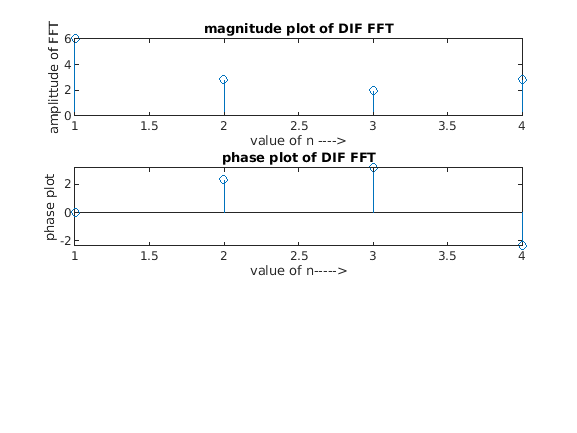

magnitude=abs(X);
subplot(3,1,1)
stem(magnitude);
xlabel('value of n ---->');
ylabel('amplittude of FFT');
title('magnitude plot of DIF FFT');
phase=angle(X);
subplot(3,1,2)
stem(phase);
xlabel('value of n----->');
ylabel('phase plot');
title('phase plot of DIF FFT');